AR = 10.69;
ZeroLiftAngle = -3;
%TaperRatio = 0.6;
b = 118/2

b = 59

AoA = 0

AoA = 0

Cr = 13.8

Cr = 13.8000

LiftCurveSlope = 2*pi

LiftCurveSlope = 6.2832


eval = 100

eval = 100


TaperRatio = (0:0.01:1)

TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


    
e = zeros(1,length(TaperRatio))

e =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for h = 1:length(TaperRatio)
    
    interval = 90/(eval+1)
    
    angles = zeros(1, eval+1)
    angles(1) = 90
    
    for i = 1:eval
        
        angles(i+1) = 90-i*interval;
        
    end
    
    Chord = zeros(1,eval+1)
    
    for i = 1:eval
        Chord(1,i+1) = Cr*((TaperRatio(h)-1)*cosd(angles(i))+1);           %Fills matrix of chord values at evaluated phi locations.
    end
    
    mu = zeros(1,eval+1);
    for i = 1:length(Chord)
        mu(1,i) = (Chord(1,i)*LiftCurveSlope)/(4*b);                  %Fills matrix of mu values using matrix of chord values.
    end
    
    Right_Coefficients = zeros(eval+1,4);                                      %Initializes matrices to hold the coefficients on right and left side of lifting line equation.
    Left_Coefficients = zeros(1,eval+1);
    
    for i = 1:eval+1                                                           %Fills left and right coefficient matrices using lifting line equation.
        for j = 1:eval+1
            Right_Coefficients(i,j) = sind((j*2-1)*angles(1,i))*((j*2-1)*mu(1,i)+sind(angles(1,i)));
        end
        Left_Coefficients(1,i) = mu(1,i)*(AoA - ZeroLiftAngle)*sind(angles(1,i));
    end
    
    A_Values = Right_Coefficients\Left_Coefficients';
    
    delta = 0;
    
    for x=1:eval
        
        delta = delta + (A_Values(x+1)/A_Values(1))^2;
        
    end
    
    e(h) = 1/(1+delta)
    
end

interval = 0.8911

angles =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles =     90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e =     0.9542         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles =     90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e =     0.9542    0.9587         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles =     90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e =     0.9542    0.9587    0.9623         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles =     90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e =     0.9542    0.9587    0.9623    0.9654         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles =     90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e =     0.9542    0.9587    0.9623    0.9654    0.9679         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles =     90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e =     0.9542    0.9587    0.9623    0.9654    0.9679    0.9700         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles =     90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e =     0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles =     90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e =     0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles =     90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e =     0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles =     90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e =     0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles =     90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e =     0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles =     90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e =     0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791         0         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792         0         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793         0         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794         0         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793         0         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792         0         0         0         0         0         0         0         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791         0         0         0         0         0         0         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789         0         0         0         0         0         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787         0         0         0         0         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785         0         0         0         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782         0         0         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779         0         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776         0         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772         0


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


interval = 0.8911

angles = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles = 1×30
    90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Chord = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×30
    0.9542    0.9587    0.9623    0.9654    0.9679    0.9700    0.9719    0.9734    0.9747    0.9758    0.9767    0.9774    0.9780    0.9785    0.9788    0.9791    0.9792    0.9793    0.9794    0.9793    0.9792    0.9791    0.9789    0.9787    0.9785    0.9782    0.9779    0.9776    0.9772    0.9768


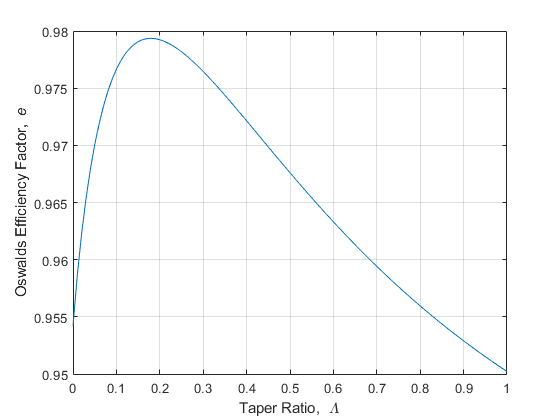





    
% phi = zeros(1,91)
% 
% SumOfSines=0
% 
% ClCL = zeros(1,length(phi))
% 
% for j = 1:91
%     
%     phi = j
%     
%     SumOfSines=0
%     
%     for i = 1:eval+1
%         
%         SumOfSines = SumOfSines + A_Values(i)*sind((2*i-1)*phi);  
%         
%     end
%     
%     ClCL(j) = 2*(1+TaperRatio)/(pi*A_Values(1))*1/((TaperRatio-1)*cosd(phi)+1)*SumOfSines;
%   
% end
% 
% y = zeros(1,length(phi));
% 
% for k = 1:91
%     
%     y(k) = cosd(acosd((k-1)/90));
%     
% end
% 
% plot(y,ClCL)


plot(TaperRatio,e)
xlabel('Taper Ratio, {\it \Lambda}')
ylabel('Oswalds Efficiency Factor, {\it e}')
grid on